# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './data/COVID19/country.csv';
path_daily = './data/COVID19/daily_info.csv';

## 第一部分（主成分分析 + 聚类分析 + LSTM预测）

### 第一步（主成分分析 + 聚类分析）

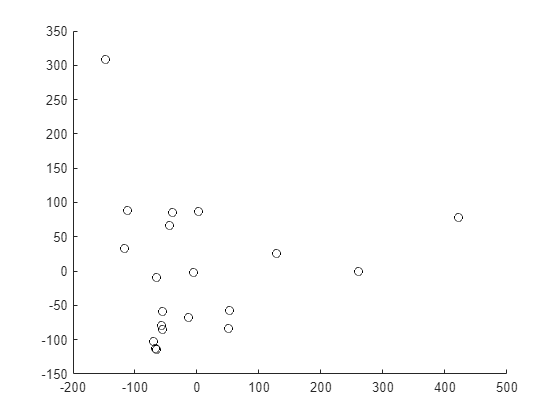

% 导入数据
country_SA = StatisticsAnalysis('TablePath', path_country);
country = country_SA.Table;
daily_SA = StatisticsAnalysis('TablePath', path_daily, ...
    'ImportOptions', {'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}} ...
    );
daily = daily_SA.Table;
% 每日数据所涉及的国家
daily_location = unique(daily{:,'location'});
% 国家数据中被涉及的、无缺的的行
country_location = unique(country{:,'location'});
%     country_daily = country;
country_daily = country(ismember(country_location, daily_location), :);
country_daily(any(ismissing(country_daily)')',:) = [];
% 疫情管控力度、累计病例-总人口比
MeanStingency = zeros(size(country_daily, 1), 1);
StdStingency = MeanStingency;
CasesPerCapita = MeanStingency;
for idx = 1: size(country_daily, 1)
    tp = daily_SA.WholeTable{strcmp(daily_SA.WholeTable.location,country_daily{idx, 'location'}),'stringency_index'};
    MeanStingency(idx) = tsnanmean(tp);
    StdStingency(idx) = tsnanstd(tp);
    tp = daily_SA.WholeTable{strcmp(daily_SA.WholeTable.location,country_daily{idx, 'location'}),'total_cases'};
    CasesPerCapita(idx) = tsnanmax(tp) / country_daily{idx, 'population'};
end
country_daily = addvars(country_daily, MeanStingency, 'NewVariableNames', 'stingency_index_Mean');
country_daily = addvars(country_daily, StdStingency, 'NewVariableNames', 'stingency_index_std');
country_daily = addvars(country_daily, CasesPerCapita, 'NewVariableNames', 'total_cases_per_capita');
% 数据准备
country_daily = removevars(country_daily, {'continent', 'population', 'gdp_per_capita'});
country_daily = addvars(country_daily, (country_daily.male_smokers+country_daily.female_smokers)/2, 'NewVariableNames', 'smokers');
country_daily = removevars(country_daily, {'male_smokers', 'female_smokers'});
data = table2array(removevars(country_daily,'location'));
% 主成分分析
[coeff, score, latent] = pca(data);
ratio = latent/sum(latent);
data_cut = score(:,3:end);
% dbscan
% idxx = dbscan(data_cut, 65, 2);
% k-mean
idxx = kmeans(data, 4);
figure(1); scatter(score(:,1), score(:,2), 'black');

country_types = cell(length(unique(abs(idxx))),1);
noise_points = cell.empty;
for ii = 1:size(idxx,1)
    type = idxx(ii,1);
    if type == -1
        display(['noise point ', country_daily{ii,'location'}{1}]);
        noise_points = [noise_points, country_daily{ii,'location'}];
    else
        country_types{type,1} = [country_types{type,1}, country_daily{ii,'location'}];
    end
end
% 显示分类
for ii = 1: size(country_types,1), country_types{ii,2} = length(country_types{ii,1}); end
[~, index] = sort(cell2mat(country_types(:,2)));
country_types = country_types(index, 1);
for ii = 1: size(country_types,1), display(country_types{ii,1}); end

  1×1 cell array

    {'Egypt'}

  1×2 cell array

    {'Japan'}    {'South Korea'}

  1×5 cell array

  Columns 1 through 4

    {'China'}    {'Hungary'}    {'Malaysia'}    {'Saudi Arabia'}

  Column 5

    {'Zimbabwe'}

  1×12 cell array

  Columns 1 through 5

    {'Australia'}    {'Canada'}    {'Chile'}    {'Ethiopia'}    {'France'}

  Columns 6 through 10

    {'Germany'}    {'Iceland'}    {'Ireland'}    {'South Africa'}    {'Sweden'}

  Columns 11 through 12

    {'Thailand'}    {'United States'}



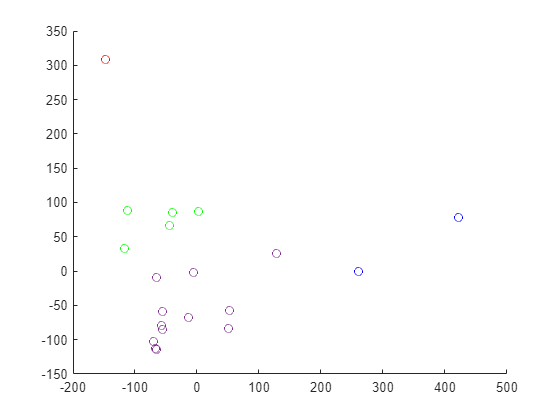

% 可视化分类结果
color = {'r', 'b', 'g', 'o', 'y', 'cyan'};
for ii = 1: size(country_types,1)
    map = ismember(country_daily{:,'location'},country_types{ii,1});
    figure(2); scatter(score(map,1), score(map,2), color{ii}); hold on
end
map = ismember(country_daily{:,'location'},noise_points);
figure(2); scatter(score(map,1), score(map,2), 'black'); hold off

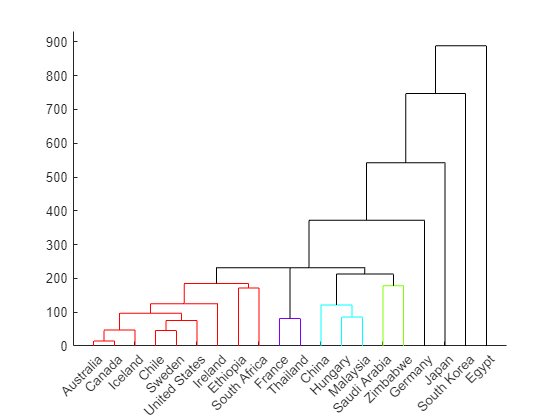

% 
Y = pdist(score);
Y = squareform(Y);
Z = linkage(Y);
dendrogram(Z, 'Labels', country_daily{:,'location'}, 'ColorThreshold', 200);

## 附录A（StatisticsAnalysis的使用方法）

% 导入法国在2020年的新增与累计接种疫苗人次
daily_SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', { ...
            'new_vaccinations', 'double', ...
            'total_vaccinations', 'double' ...
            }, ...
        'SelectedVariableNames', ...
            {'date', 'new_vaccinations', 'total_vaccinations'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France', ...
        'date', timerange("2020-01-01", "2020-12-31", 'closed') ...
        } ...
    );
daily = daily_SA.TimeTable

daily = 343×2 timetable
       date       new_vaccinations    total_vaccinations
    __________    ________________    __________________

    2020-01-24          NaN                  NaN        
    2020-01-25          NaN                  NaN        
    2020-01-26          NaN                  NaN        
    2020-01-27          NaN                  NaN        
    2020-01-28          NaN                  NaN        
    2020-01-29          NaN                  NaN        
    2020-01-30          NaN                  NaN        
    2020-01-31          NaN                  NaN        
    2020-02-01          NaN                  NaN        
    2020-02-02          NaN                  NaN        
    2020-02

% 再导入法国在2020年的新增与累计病例数
daily2 = daily_SA.Update('ImportOptions', { ...
        'SelectedVariableNames', {'date', 'new_cases', 'total_cases'} ...
        }...
    ).TimeTable

daily2 = 343×2 timetable
       date       new_cases    total_cases
    __________    _________    ___________

    2020-01-24        2             2     
    2020-01-25        1             3     
    2020-01-26        0             3     
    2020-01-27        0             3     
    2020-01-28        1             4     
    2020-01-29        1             5     
    2020-01-30        0             5     
    2020-01-31        0             5     
    2020-02-01        1             6     
    2020-02-02        0             6     
    2020-02-03        0             6     
    2020-02-04        0             6     
    2020-02-05        0             6     
    <s

% 对法国在2020年的新增与累计病例数进行缺失值处理
% 先进行探测
daily_SA.MissingValuesReport

ans = struct with fields:
            Map: [343×3 logical]
           date: {}
      new_cases: {1×8 cell}
    total_cases: {}


% 编写参数，进行处理
MissingValuesOptions = { {'new_cases', 'total_cases'}, 'Increment-Addition', ...
        {'InterpolationStyle','LinearRound', ...
        'RemoveFirstRows',false,'RemoveLastRows',false}
    };
daily2 = daily_SA.Update('MissingValuesOptions', MissingValuesOptions).TimeTable

daily2 = 343×2 timetable
       date       new_cases    total_cases
    __________    _________    ___________

    2020-01-24        2             2     
    2020-01-25        1             3     
    2020-01-26        0             3     
    2020-01-27        0             3     
    2020-01-28        1             4     
    2020-01-29        1             5     
    2020-01-30        0             5     
    2020-01-31        0             5     
    2020-02-01        1             6     
    2020-02-02        0             6     
    2020-02-03        0             6     
    2020-02-04        0             6     
    2020-02-05        0             6     
    <s

% 更多关于缺失值的信息
daily_SA.MissingValuesReport.increment_addition_new_cases_total_cases

ans = struct with fields:
              Increment: 'new_cases'
               Addition: 'total_cases'
         IncrementWhere: [0 1 0]
          AdditionWhere: [0 0 1]
    IncrementMissingMap: [343×1 logical]
     AdditionMissingMap: [343×1 logical]
     DecreasingAddition: {1×9 cell}
          MissingBlocks: [8×1 struct]
        tpMissingBlocks: [8×1 struct]
     MissingBlocksGroup: [8×1 struct]


## 附录B（利用所给数据可以进行的可视化）

利用StatisticsAnalysis对象，一步完成（1）导入参数的检测、修改；（2）数据的导入；（3）表格的检索；（4）一般统计指标的计算.

### Example 1: 法国2020年至2022年4月的每日新增阳性与每日新增疫苗接种量图像

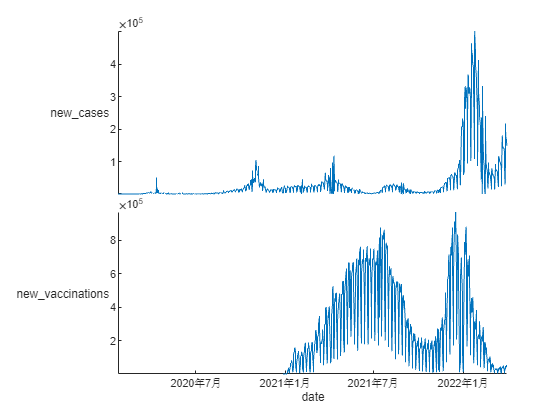

daily_SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', {'new_vaccinations', 'double', 'total_vaccinations', 'double'}, ...
        'SelectedVariableNames', {'date', 'new_cases', 'new_vaccinations'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France', ... Country
        'date', arange(["2020-01-01", "2022-04-01"], 'closed') ... Time Range
        }, ...
    'TagsGenerateOptions', { ...
        'CustomTagName', {'increment', [0 1 1], 'continuous', [0 1 1]}, ...
        'CustomTagFunction', { ...
            'increment', 'SummationOfIncrements', @(x,y)tsnansum(x{:,:}) ...
            } ...
        }...
    );
daily = daily_SA.TimeTable;
figure(1); stackedplot(daily);

daily.Properties

ans =   TimetableProperties with properties:

               Description: ''
                  UserData: []
            DimensionNames: {'date'  'Variables'}
             VariableNames: {'new_cases'  'new_vaccinations'}
      VariableDescriptions: {}
             VariableUnits: {}
        VariableContinuity: []
                  RowTimes: [799×1 datetime]
                 StartTime: 2020-01-24
                SampleRate: NaN
                  TimeStep: 1d

   Custom Properties (access using t.Properties.CustomProperties.<name>):
     detectedImportOptions: [1×1 matlab.io.text.DelimitedTextImportOptions]
                      Tags: [16×3 table]
                      Size: [799 3]
                  TagNames: {{2×1 cell}  {2×1 cell}}
               UniqueCount: {[748]  [460]}
                ValueClass: {'double'  'double'}
              MissingCount: {[10]  [339]}
              MissingRatio: {[0.01

### Example 2: 缺失值处理前后累计病例数据的对比图像

daily = table2timetable(daily_SA.FullVarTable);
MissingValuesOptions = { {'new_cases', 'total_cases'}, 'Increment-Addition', ...
        {'InterpolationStyle','LinearRound', ...
        'RemoveFirstRows',false,'RemoveLastRows',false}
    };
daily2 = daily_SA.RenewSelectedVariableNames.Update('MissingValuesOptions', MissingValuesOptions).TimeTable

daily2 = 799×12 timetable
       date        location     continent     new_cases    total_cases    new_tests    total_tests    positive_rate    new_vaccinations    total_vaccinations    hosp_patients    icu_patients    stringency_index
    __________    __________    __________    _________    ___________    _________    ___________    _____________    ________________    __________________    _____________    ____________    ________________

    2020-01-24    {'France'}    {'Europe'}        2             2            NaN           N

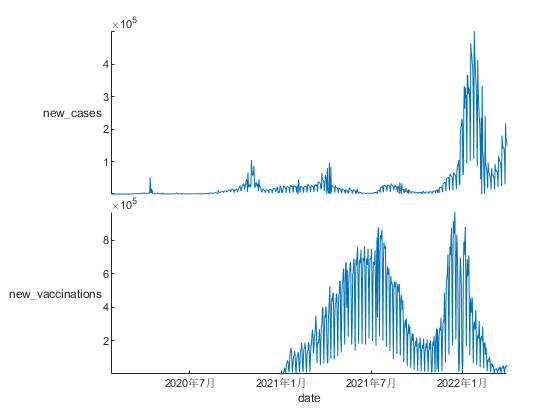

figure(2); stackedplot(daily2(:,{'new_cases', 'new_vaccinations'})); % 下面是缺失值处理后的数据作图

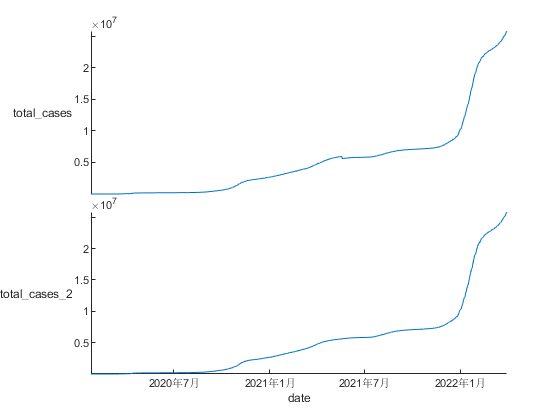

figure(3); stackedplot([ ...
    daily(:,'total_cases'), ...
    renamevars(daily2(:,'total_cases'), 'total_cases', 'total_cases_2')...
    ]);

### Example 3: 法国2020年至2022年4月ICU患者占全体住院患者的比例变化趋势图

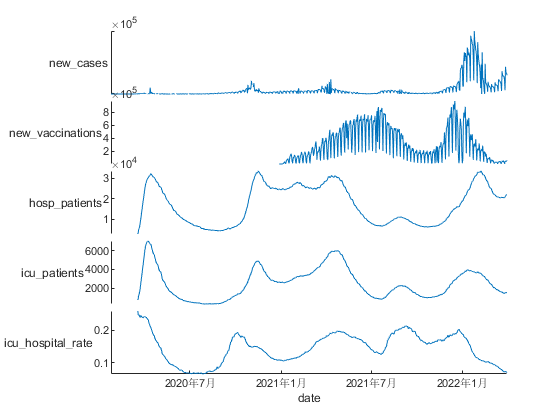

Ratio = daily_SA.FullVarTable(:, 'icu_patients');
Ratio = renamevars(Ratio, 'icu_patients', 'icu_hospital_rate');
for idx = 1: size(Ratio, 1)
    Ratio{idx,'icu_hospital_rate'} = Ratio{idx,'icu_hospital_rate'} ./ daily_SA.FullVarTable{idx,'hosp_patients'};
end
figure(4); stackedplot([ ...
    daily(:,{'new_cases','new_vaccinations'}), ...
    daily_SA.FullVarTable(:,{'hosp_patients', 'icu_patients'}), ...
    Ratio...
    ]);

### Example 4: 不同国家的阳性率变化趋势

阳性率(positive rate)是在特定国家/地区的核酸检测中有多少份额确诊。当一个国家的阳性测试率较低时，说明这些国家为防止疫情大规模爆发做出了很多努力；红色表示核酸检测阳性率高，这表明感染的真实数量可能远远高于确诊病例数。

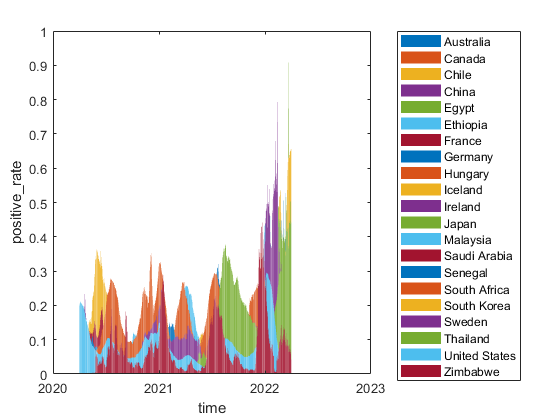

Country = unique(daily_SA.WholeTable{:,'location'}');
daily_SA = daily_SA.Update('ImportOptions', {'SelectedVariableNames', {'date', 'positive_rate'}});
daily_SA = daily_SA.Update('SelectTableOptions', {'date', arange(["2020-04-01", "2022-04-01"], 'closed')});
HighestRate = zeros(1,21);
for idx = 1: length(Country)
    country_name = Country{idx};
    tpPosRate = daily_SA.Update('SelectTableOptions', {'location', country_name}).TimeTable;
    tpPosRate = renamevars(tpPosRate, 'positive_rate', country_name);
    if idx == 1, posRate = tpPosRate;
    else, posRate = [posRate, tpPosRate];
    end
    HighestRate(idx) = tsnanmax(tpPosRate{:,1});
    figure(5); bar(tpPosRate.date, tpPosRate.(country_name)); datetick x; hold on
end
hold off; legend(Country{:}, 'Location', 'NorthEastOutside');
xlabel('time'); ylabel('positive\_rate');

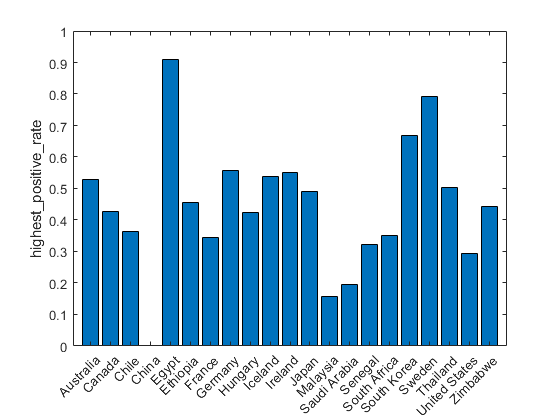

figure(6); bar(categorical(Country), HighestRate); ylabel('highest\_positive\_rate');% 历时最高阳性率

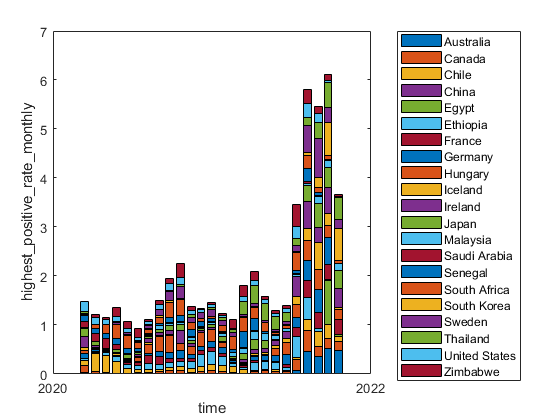

% retime函数可以将日期整合成组，并按照给定方式统计
posRateMonthly = retime(posRate, "monthly", "max");
figure(7); bar(posRateMonthly.date, posRateMonthly{1:end,1:end}, 'stacked'); datetick x;
legend(Country{:}, 'Location', 'NorthEastOutside');
xlabel('time'); ylabel('highest\_positive\_rate\_monthly');

## 第五部分：分析预测

country_names = {'China','France','Ethiopia','Zimbabwe','Hungary','South Korea','Egypt','Australia','Canada','Iceland'};
[XSeq_train, YSeq_train, XSeq_test, YSeq_test, muY, sigY] = Data_Preparation(country_names,true);

Training:

net = PredictNet(XSeq_train,YSeq_train);

Testing:

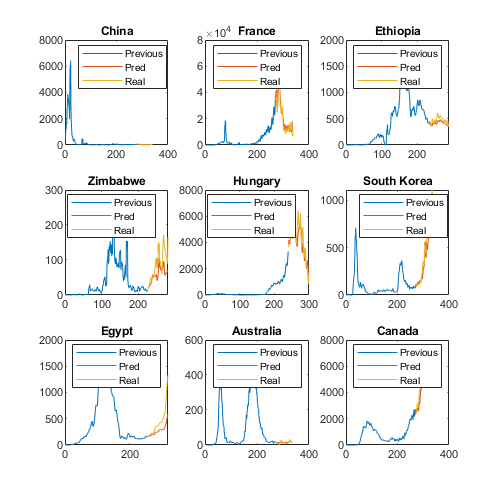

   0.050516809263215

   0.323391189157043

   0.869391266286694

   0.698677279775290

   0.210970222680379

   0.253667350602448

   0.880391652617718

   0.066094252556610

   0.188611402595327



clf;
set(gcf,'position',[250 300 500 500])
for NUM = 1:9
Xtest = XSeq_test{NUM,1};
Ytest = YSeq_test{NUM,1};
net = resetState(net);
net = predictAndUpdateState(net,XSeq_train{NUM,1});
numTimeStepsTest = size(Xtest,2);
YPred = zeros(1,numTimeStepsTest);
for i = 1:numTimeStepsTest
    [net,YPred(1,i)] = predictAndUpdateState(net,Xtest(:,i),'ExecutionEnvironment','gpu');
end
relerr = norm(YPred-Ytest)/norm(Ytest);
disp(relerr)
YPred = (YPred * sigY{1,NUM}) + muY{1,NUM};
Ytest = (Ytest * sigY{1,NUM}) + muY{1,NUM};
% previous
Yprevious = (YSeq_train{NUM,1}*sigY{1,NUM}) + muY{1,NUM};

subplot(3,3,NUM);
plot(1:size(Yprevious,2),Yprevious);
hold on;
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),YPred);
plot(size(YSeq_train{NUM,1},2)+1:size(YSeq_train{NUM,1},2)+size(YPred,2),Ytest);
l = legend('Previous','Pred','Real','Location','Best');
title(country_names{1,NUM});

end

% SEIR
% myfitVirusCV19(@getDataTest)